clear all;
close all;
clc;

%load data written by NY

Animal = 'tph189';
Date = '20230418';
totalTrial = 150;
Key = 'uniform';
target_fps = 20;
F_over_dV = -372; %-192.4; %-372;
force_thres = 100000; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'behavior.csv']); %,'NumHeaderLines',1);
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
resistance_table = readtable([data_folder filesep 'resistance.csv']);%,'NumHeaderLines',1);

behavior_table = readtable([data_folder filesep 'behavior.csv']); %,'NumHeaderLines',1);

% define each task related variable
resistance = resistance_table.('resistance'); % state1: 8 (light) or 20 (heavy)
trial = behavior_table.('trial_'); % 1-150, 0: out of trial 
position = behavior_table.('position'); % state2: 630-647
force = behavior_table.('dVoltage'); % action: 0 ~ 0.8?
reward = behavior_table.('pumpReward'); % reward: 0 or 1 in end of trial
time = behavior_table.('time'); % time points (ms)

force = force*F_over_dV;

% deal with the problem fps are changed through recording 
% averaging and make data 20 fps?
% change timebin to target fps
% from time determine start time and end time of each trial

duration = round((time(length(time))-time(1)) / (1000/target_fps));
time_transformed = transpose(0:(1000/target_fps):duration*(1000/target_fps));
transformed_times = zeros(1,length(time));
for j_step = 1:length(time)
    transformed_time = round((time(j_step)-time(1)) / (1000/target_fps));
    transformed_times(j_step) = transformed_time+1;
end
% take average of position and force assigned to the same timebin
% take max     of reward             assigned to the same timebin   
position_temp   = zeros(duration+1,1);
force_temp      = zeros(duration+1,1);
reward_temp     = zeros(duration+1,1);
trial_temp      = zeros(duration+1,1);
resistance_temp = zeros(duration+1,1);
trial_start_temp = zeros(duration+1,1);
trial_end_temp   = zeros(duration+1,1);
for j_step = 1:duration+1
    step_idx = find(transformed_times == j_step);
    if isempty(step_idx)
        position_temp(j_step) = NaN;
        force_temp(j_step) = NaN;
        reward_temp(j_step)= NaN;
        trial_temp(j_step) = NaN;
        resistance_temp(j_step) = NaN;
        trial_start_temp(j_step) = NaN;
        trial_end_temp(j_step)   = NaN;
    else
        position_step_temp = mean(position(step_idx));
        force_step_temp    = mean(force(step_idx));
        reward_step_temp   = max(reward(step_idx));
        [a, nearest_idx]   = min(abs(time(step_idx)-time(1)-(transformed_times(j_step)-1)*(1000/target_fps)));
        trial_step_temp    = trial(step_idx(nearest_idx));
        position_temp(j_step) = position_step_temp;
        force_temp(j_step) = force_step_temp;
        reward_temp(j_step)= reward_step_temp;
        trial_temp(j_step) = trial_step_temp;
        if trial_step_temp == 0
            resistance_temp(j_step) = inf;
        else
            resistance_temp(j_step) = resistance(trial_step_temp);
        end
        % determine trial based on nearest time of the timebin
        if j_step ~= 1
            if trial_temp(j_step)>trial_temp(j_step-1)
                trial_start_temp(j_step) = 1;
                trial_end_temp(j_step-1)     = 0;
            elseif trial_temp(j_step)<trial_temp(j_step-1)
                trial_start_temp(j_step) = 0;
                trial_end_temp(j_step-1)     = 1;
            else
                trial_start_temp(j_step) = 0;
                trial_end_temp(j_step-1)     = 0;          
            end
        end
    end
end
behavior_raw_fps = [time_transformed, trial_temp, trial_start_temp, trial_end_temp, resistance_temp, position_temp, force_temp, reward_temp]; 

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_raw_fps');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_raw_fps');

% set raised cosine fileter
trial_start_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
trial_end_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
resistance_high_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
resistance_low_filter  = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
position_filter = rcosdesign(0.25,8,4); % 6 evenly spaced functions 
force_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
reward_filter = rcosdesign(0.25,8,8); % 7 functions 2 s forward and 1 s backward

% convolv using raised cosine function
trial_start_conv = zeros(length(trial_start_temp),5);
trial_end_conv = zeros(length(trial_end_temp),5);
resistance_high_conv = zeros(length(resistance_temp),5);
resistance_low_conv  = zeros(length(resistance_temp),5);  
position_conv = zeros(length(position_temp),6);
force_conv = zeros(length(force_temp),5);
reward_conv = zeros(length(reward_temp),5);

trial_start_conv_temp = conv(trial_start_temp,trial_start_filter);
trial_end_conv_temp = conv(trial_end_temp,trial_end_filter);
% transform resistance vector to one-hot vector
resistance_categorical = categorical(resistance_temp);
resistance_one_hot = onehotencode(resistance_categorical,2); % catergories are (8,20,inf)
resistance_high_conv_temp = conv(resistance_one_hot(:,2),resistance_high_filter);
resistance_low_conv_temp  = conv(resistance_one_hot(:,1),resistance_low_filter);
force_conv_temp = conv(force_temp,force_filter);
reward_conv_temp = conv(reward_temp,reward_filter);

for i = 1:5
    % slide 0.5 sec (10 time step) temporal window 
    % filter width 32
    trial_start_conv(:,i) = trial_start_conv_temp(33+10*(3-i):32+10*(3-i)+length(trial_start_temp));
    trial_end_conv(:,i) = trial_end_conv_temp(33+10*(3-i):32+10*(3-i)+length(trial_end_temp));
    resistance_high_conv(:,i) = resistance_high_conv_temp(33+10*(3-i):32+10*(3-i)+length(resistance_temp));
    resistance_low_conv(:,i)  = resistance_low_conv_temp(33+10*(3-i):32+10*(3-i)+length(resistance_temp));    
    force_conv(:,i) = force_conv_temp(33+10*(3-i):32+10*(3-i)+length(force_temp));
end

reward_conv_temp = cat(1,reward_conv_temp,zeros(8,1));
for i = 1:7
    % slide 0.5 sec (10 time step) temporal window 
    % filter width 32
    reward_conv(:,i) = reward_conv_temp(33+10*(5-i):32+10*(5-i)+length(reward_temp));
end

% transform position_temp to position vector timeseries
position_vector_timeseries = zeros(length(position_temp),18);
position_floor = min(max(floor(position_temp)-629,1),18);
position_temp_transformed = min(max(position_temp-629,1),18);
% position_conv_temp = zeros(length(position_temp),50);
for j_step = 1:length(position_temp)
    position_decimal = position_temp_transformed(j_step) - position_floor(j_step);
    if position_decimal == 0
        position_vector_timeseries(j_step,position_floor(j_step)) = 1;
    else
        position_vector_timeseries(j_step,position_floor(j_step)) = position_temp_transformed(j_step) - position_floor(j_step);
        position_vector_timeseries(j_step,position_floor(j_step)+1) = 1 - position_vector_timeseries(j_step,position_floor(j_step));
    end
    position_conv_temp= conv(position_vector_timeseries(j_step,:),position_filter);
    for i = 1:6    
        % filter pos (629,633,637,641,645,649) 
        % filter width 16
        position_conv(j_step,i) = position_conv_temp(16+19-4*(i-1));
    end
end

% normalized each convolved timesries
behavior_convolved = [trial_start_conv, trial_end_conv, resistance_high_conv, resistance_low_conv, position_conv, force_conv, reward_conv]; 
% behavior_convolved_zscored = zscore(behavior_convolved);
behavior_convolved_mu = mean(behavior_convolved,'omitnan');
behavior_convolved_sigma = std(behavior_convolved,'omitnan');
behavior_convolved_zscored = (behavior_convolved-repmat(behavior_convolved_mu,length(behavior_convolved),1)./repmat(behavior_convolved_sigma,length(behavior_convolved),1));

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_convolved_zscored');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_convolved_zscored');

% neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
neural_activity_table = readtable([data_folder filesep 'cell_traces.csv']);%,'NumHeaderLines',1); #Linux
neural_activity_time = table2array(neural_activity_table(:,1))*(10^3)

neural_activity_time = 1.0e+06 *

         0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009


% deal with the problem fps are changed through recording 
% aligning to the neural activity recording timescale
% change timebin to target fps
% from time determine start time and end time of each trial

duration = length(neural_activity_time);
% time_transformed = transpose(0:(1000/target_fps):duration*(1000/target_fps));
transformed_times = zeros(1,length(time));
temp_time_idx = 1; 
for j_step = 1:length(time)
    for i = 1:length(neural_activity_time)-temp_time_idx
        if abs(time(j_step)-time(1)-neural_activity_time(temp_time_idx+1)) < abs(time(j_step)-time(1)-neural_activity_time(temp_time_idx))
            temp_time_idx = temp_time_idx+1;
        else
            break
        end
    end
%     transformed_time = neural_activity_time(temp_time_idx);
    transformed_times(j_step) = temp_time_idx;
end
% take average of position and force assigned to the same timebin
% take max     of reward             assigned to the same timebin   
position_temp   = zeros(duration,1);
force_temp      = zeros(duration,1);
reward_temp     = zeros(duration,1);
trial_temp      = zeros(duration,1);
resistance_temp = zeros(duration,1);
trial_start_temp = zeros(duration,1);
trial_end_temp   = zeros(duration,1);
for j_step = 1:duration
    step_idx = find(transformed_times == j_step);
    if isempty(step_idx)
        position_temp(j_step) = NaN;
        force_temp(j_step) = NaN;
        reward_temp(j_step)= NaN;
        trial_temp(j_step) = NaN;
        resistance_temp(j_step) = NaN;
        trial_start_temp(j_step) = NaN;
        trial_end_temp(j_step)   = NaN;
    else
        position_step_temp = mean(position(step_idx));
        force_step_temp    = mean(force(step_idx));
        reward_step_temp   = max(reward(step_idx));
        [a, nearest_idx]   = min(abs(time(step_idx)-time(1)-neural_activity_time(j_step)));
        trial_step_temp    = trial(step_idx(nearest_idx));
        position_temp(j_step) = position_step_temp;
        force_temp(j_step) = force_step_temp;
        reward_temp(j_step)= reward_step_temp;
        trial_temp(j_step) = trial_step_temp;
        if trial_step_temp == 0
            resistance_temp(j_step) = inf;
        else
            resistance_temp(j_step) = resistance(trial_step_temp);
        end
        % determine trial based on nearest time of the timebin
        if j_step ~= 1
            if trial_temp(j_step)>trial_temp(j_step-1)
                trial_start_temp(j_step) = 1;
                trial_end_temp(j_step-1)     = 0;
            elseif trial_temp(j_step)<trial_temp(j_step-1)
                trial_start_temp(j_step) = 0;
                trial_end_temp(j_step-1)     = 1;
            else
                trial_start_temp(j_step) = 0;
                trial_end_temp(j_step-1)     = 0;          
            end
        end
    end
end
behavior_neural_time = [neural_activity_time, trial_temp, trial_start_temp, trial_end_temp, resistance_temp, position_temp, force_temp, reward_temp];

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_neural_time');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_neural_time');

% set raised cosine filter
trial_start_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
trial_end_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
resistance_high_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
resistance_low_filter  = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
position_filter = rcosdesign(0.25,8,4); % 6 evenly spaced functions 
force_filter = rcosdesign(0.25,8,8); % 5 functions 1 s forward and backward
reward_filter = rcosdesign(0.25,8,8); % 7 functions 2 s forward and 1 s backward

% convolv using raised cosine function
trial_start_conv = zeros(length(trial_start_temp),5);
trial_end_conv = zeros(length(trial_end_temp),5);
resistance_high_conv = zeros(length(resistance_temp),5);
resistance_low_conv  = zeros(length(resistance_temp),5);  
position_conv = zeros(length(position_temp),6);
force_conv = zeros(length(force_temp),5);
reward_conv = zeros(length(reward_temp),5);

trial_start_conv_temp = conv(trial_start_temp,trial_start_filter);
trial_end_conv_temp = conv(trial_end_temp,trial_end_filter);
% transform resistance vector to one-hot vector
resistance_categorical = categorical(resistance_temp);
resistance_one_hot = onehotencode(resistance_categorical,2); % catergories are (8,20,inf)
resistance_high_conv_temp = conv(resistance_one_hot(:,2),resistance_high_filter);
resistance_low_conv_temp  = conv(resistance_one_hot(:,1),resistance_low_filter);
force_conv_temp = conv(force_temp,force_filter);
reward_conv_temp = conv(reward_temp,reward_filter);

for i = 1:5
    % slide 0.5 sec (10 time step) temporal window 
    % filter width 32
    trial_start_conv(:,i) = trial_start_conv_temp(33+10*(3-i):32+10*(3-i)+length(trial_start_temp));
    trial_end_conv(:,i) = trial_end_conv_temp(33+10*(3-i):32+10*(3-i)+length(trial_end_temp));
    resistance_high_conv(:,i) = resistance_high_conv_temp(33+10*(3-i):32+10*(3-i)+length(resistance_temp));
    resistance_low_conv(:,i)  = resistance_low_conv_temp(33+10*(3-i):32+10*(3-i)+length(resistance_temp));    
    force_conv(:,i) = force_conv_temp(33+10*(3-i):32+10*(3-i)+length(force_temp));
end

reward_conv_temp = cat(1,reward_conv_temp,zeros(8,1));
for i = 1:7
    % slide 0.5 sec (10 time step) temporal window 
    % filter width 32
    reward_conv(:,i) = reward_conv_temp(33+10*(5-i):32+10*(5-i)+length(reward_temp));
end

% transform position_temp to position vector timeseries
position_vector_timeseries = zeros(length(position_temp),18);
position_floor = min(max(floor(position_temp)-629,1),18);
position_temp_transformed = min(max(position_temp-629,1),18);
% position_conv_temp = zeros(length(position_temp),50);
for j_step = 1:length(position_temp)
    position_decimal = position_temp_transformed(j_step) - position_floor(j_step);
    if position_decimal == 0
        position_vector_timeseries(j_step,position_floor(j_step)) = 1;
    else
        position_vector_timeseries(j_step,position_floor(j_step)) = position_temp_transformed(j_step) - position_floor(j_step);
        position_vector_timeseries(j_step,position_floor(j_step)+1) = 1 - position_vector_timeseries(j_step,position_floor(j_step));
    end
    position_conv_temp= conv(position_vector_timeseries(j_step,:),position_filter);
    for i = 1:6    
        % filter pos (629,633,637,641,645,649) 
        % filter width 16
        position_conv(j_step,i) = position_conv_temp(16+19-4*(i-1));
    end
end

% normalized each convolved timesries
behavior_neural_time_convolved = [trial_start_conv, trial_end_conv, resistance_high_conv, resistance_low_conv, position_conv, force_conv, reward_conv]; 
% behavior_convolved_zscored = zscore(behavior_convolved);
behavior_neural_time_convolved_mu = mean(behavior_neural_time_convolved,'omitnan');
behavior_neural_time_convolved_sigma = std(behavior_neural_time_convolved,'omitnan');
behavior_neural_time_convolved_zscored = (behavior_neural_time_convolved-repmat(behavior_neural_time_convolved_mu,length(behavior_neural_time_convolved),1)./repmat(behavior_neural_time_convolved_sigma,length(behavior_neural_time_convolved),1));

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_neural_time_convolved_zscored');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_neural_time_convolved_zscored');

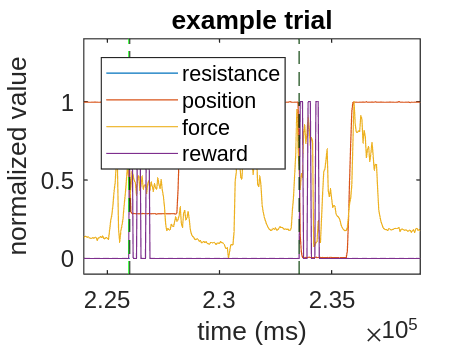

% plot example trial
% behavior_raw_fps = [time_transformed, trial_temp, trial_start_temp, trial_end_temp, resistance_temp, position_temp, force_temp, reward_temp]; 
high_res = 100;

i = 4480:4780; %3200:3500;
p_time_temp_transformed = behavior_raw_fps(i,1);
p_trial_start = behavior_raw_fps(i,3);
p_trial_end = behavior_raw_fps(i,4);
p_resistance_list = behavior_raw_fps(i,5);
p_position_temp = behavior_raw_fps(i,6);
p_force_temp = behavior_raw_fps(i,7);
p_reward_temp = behavior_raw_fps(i,8);

% p_time_temp_transformed = (p_time_temp_transformed-min(p_time_temp_transformed))/(max(p_time_temp_transformed)-min(p_time_temp_transformed));
p_resistance_list = (p_resistance_list-min(p_resistance_list))/(high_res-min(p_resistance_list));
p_position_temp = (p_position_temp-min(p_position_temp))/(max(p_position_temp)-min(p_position_temp));
p_force_temp = (p_force_temp-min(p_force_temp))/(max(p_force_temp)-min(p_force_temp));
p_reward_temp = (p_reward_temp-min(p_reward_temp))/(max(p_reward_temp)-min(p_reward_temp));

plot(p_time_temp_transformed, p_resistance_list, p_time_temp_transformed, p_position_temp, p_time_temp_transformed, p_force_temp, p_time_temp_transformed, p_reward_temp);
% plot(p_time_temp_transformed, p_position_temp, p_time_temp_transformed, p_force_temp, p_time_temp_transformed, p_reward_temp);
hold on
xline(p_time_temp_transformed(find(p_trial_start==1)),'--g');
xline(p_time_temp_transformed(find(p_trial_end==1)),'--k');

title('example trial');
xlabel('time (ms)');
ylabel('normalized value');
ylim([-0.1 1.4]);
xlim([min(p_time_temp_transformed) max(p_time_temp_transformed)]);
legend({'resistance','position','force','reward'},'Location','northwest');
% legend({'position','force','reward'},'Location','northwest');
% plot(position_temp);
% plot(force_temp);
% plot(reward_temp);
hold off

hold off

p_time_temp_transformed(find(p_trial_start==1))

ans =       225950
      233550


behavior_raw_fps(4370:4385,2)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p_resistance_list

p_resistance_list =    Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
